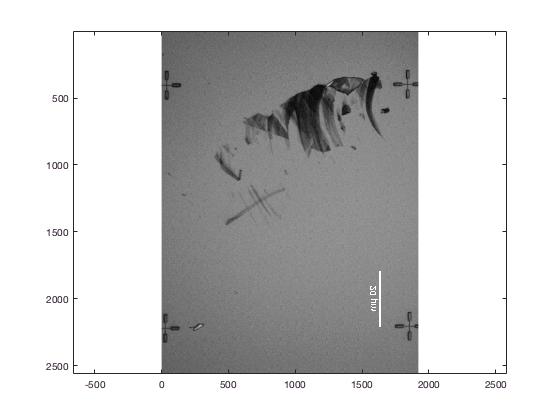

clear all
I = imread('100x.jpg');

figure
imagesc(squeeze(I(:,:,1)'))
colormap('gray')
axis('equal')

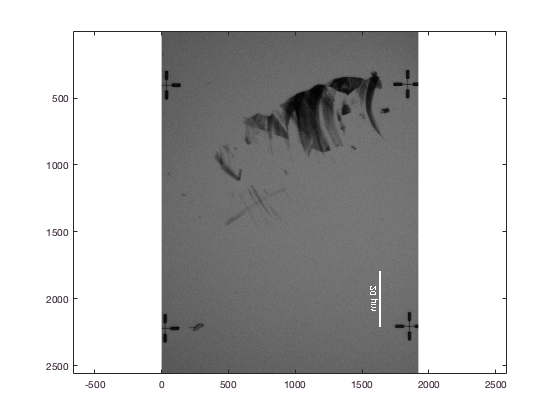


figure
imagesc(squeeze(I(:,:,2)'))
colormap('gray')
axis('equal')

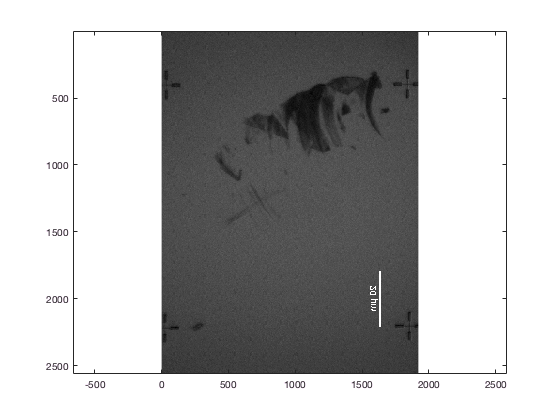

figure
imagesc(squeeze(I(:,:,3)'))
colormap('gray')
axis('equal')

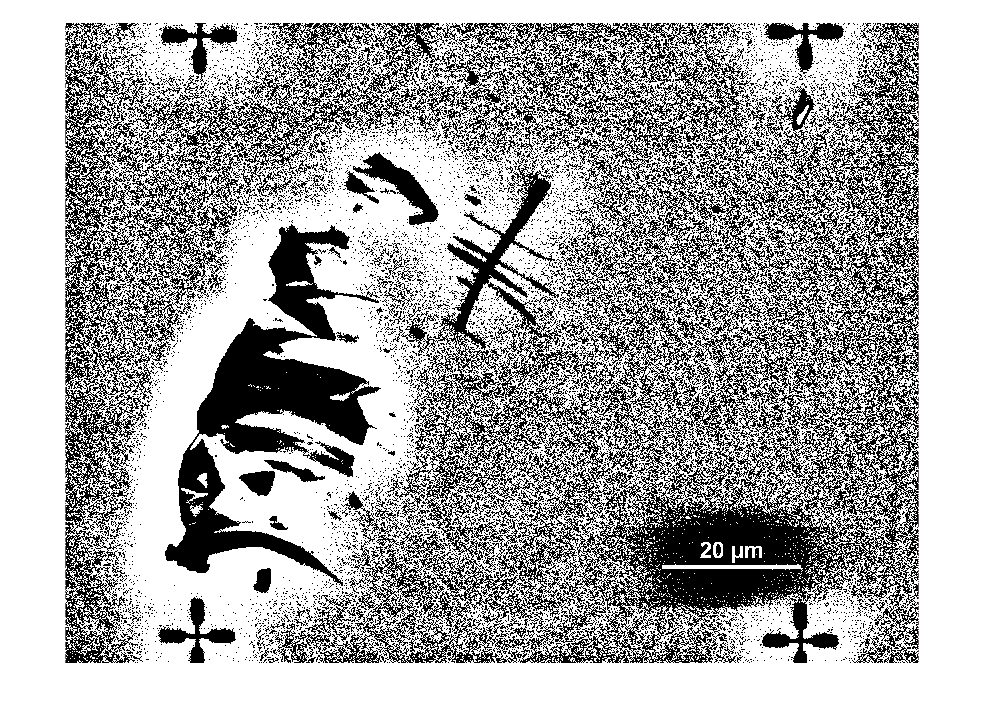

BW = imbinarize(squeeze(I(:,:,1)),'adaptive','ForegroundPolarity','dark','Sensitivity',0.6);

figure

imshow(BW)

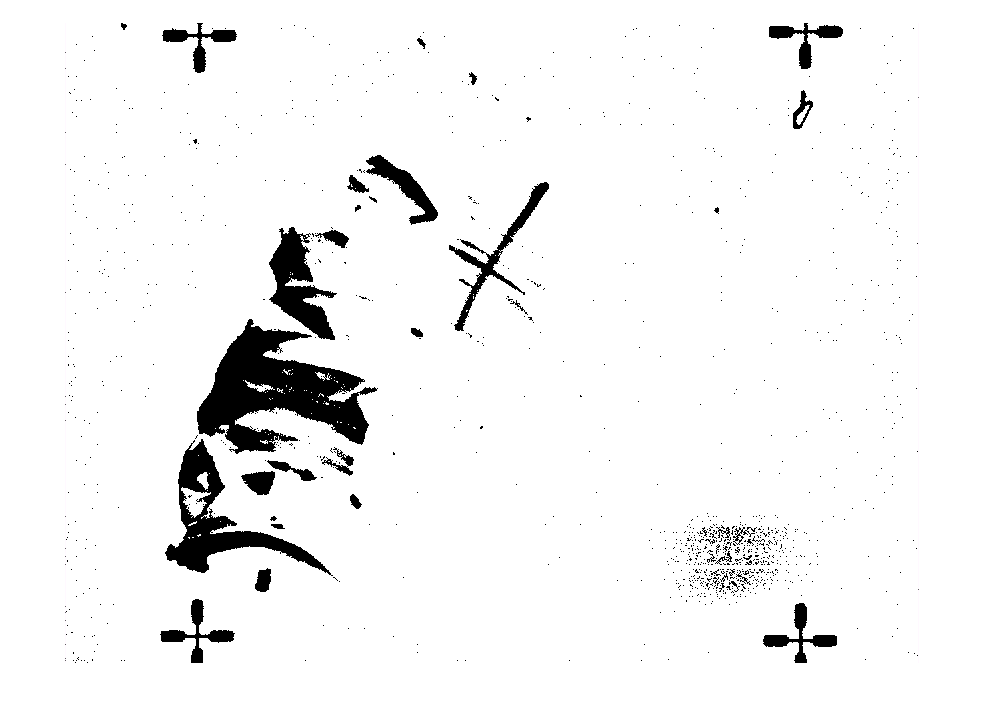

[B1,L1] = bwboundaries(BW);
BW = imbinarize(squeeze(I(:,:,1)),'adaptive','ForegroundPolarity','dark','Sensitivity',0.55);

figure

imshow(BW)

[B1,L1] = bwboundaries(BW);


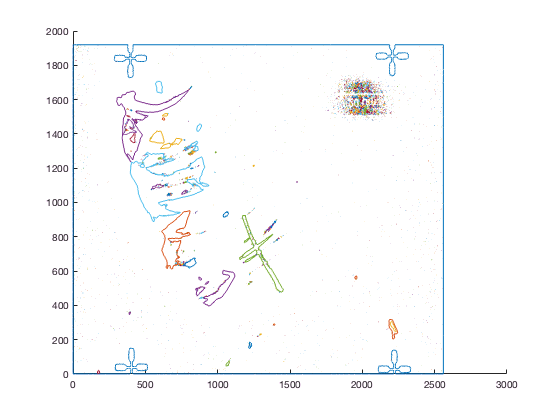

figure; hold on

for k = 1:length(B1)
boundary = B1{k};
plot(boundary(:,2), boundary(:,1), 'LineWidth', 1)
end

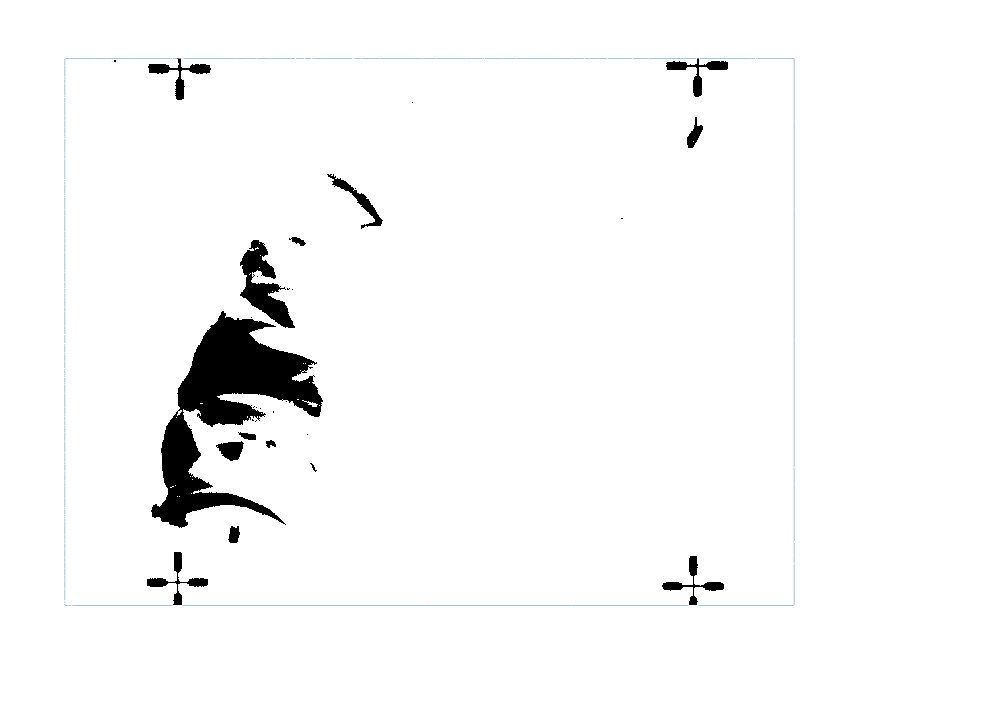

BW = imbinarize(squeeze(I(:,:,2)));

imshow(BW)

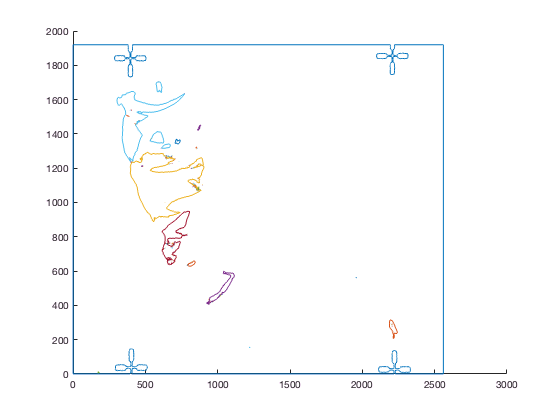

[B2,L2] = bwboundaries(BW);

figure; hold on

for k = 1:length(B2)
boundary = B2{k};
plot(boundary(:,2), boundary(:,1), 'LineWidth', 1)
end

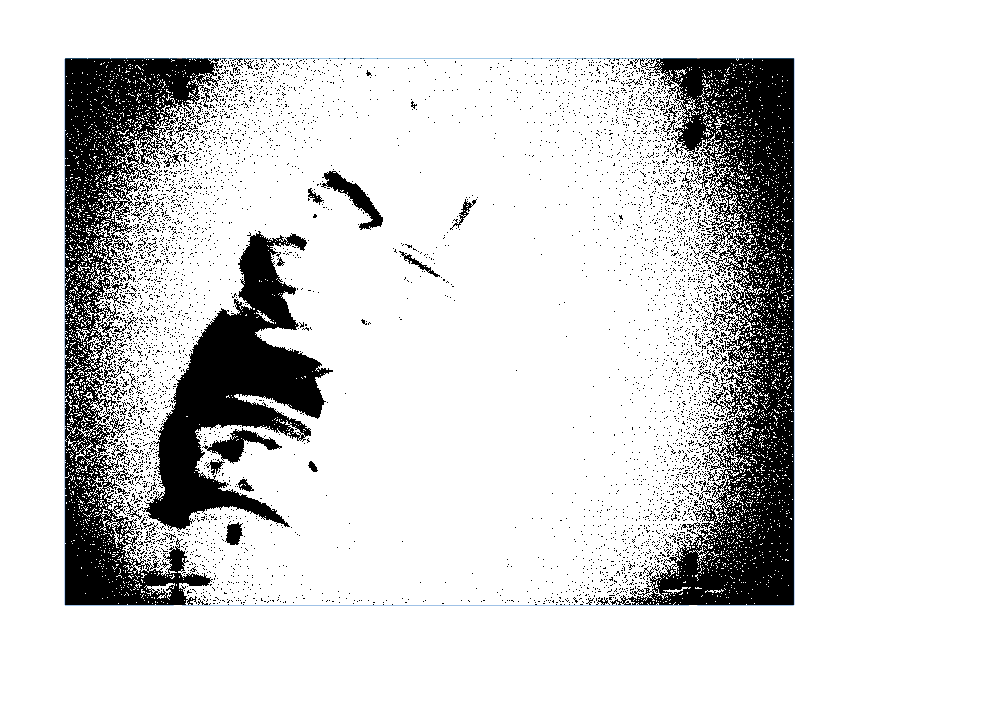

BW = imbinarize(squeeze(I(:,:,3)));
imshow(BW)

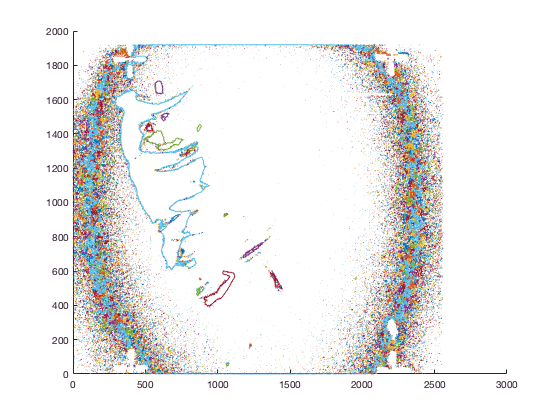

[B3,L3] = bwboundaries(BW);

figure; hold on

for k = 1:length(B3)
boun = B3{k};
plot(boun(:,2), boun(:,1), 'LineWidth', 1)
end

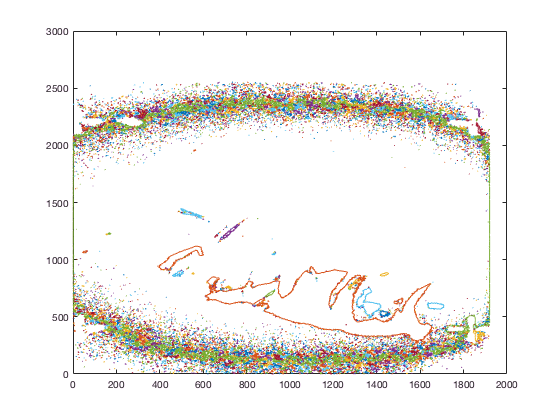

FID=dxf_prepare('mytest20.dxf');
%% So far it works. Only issue is that it seems Raith software does not open lines
%% with more of a certain number of points we need to figure out
%%
%v=[0 0; 0 20; 20 20; 20 30; 0 30];

% FID is a structure containing handle to DXF file and parameters that
% are used by remaining routines. DXFLib is a 'state' library. That means
% that certain values of parameters (e.g. color, layer) are preserved 
% between following callings to various routines unless they are changed. 
% By default, the color is ACI color 255 (white) and the layer
% number is 0. You can modify state parameters by dxf_set routine.

% Set up different color and layer. NOTE that DXF_SET always returns FID 
% structure back to you!!! You must always use the DXF_SET in the 
% following way in order to preserve changes made to the 'state' 
% parameters.
figure
% We set current Color to yellow and current layer to 20. This will be 
% used in future calls to any DXF routin until changed.
%FID = dxf_set(FID,'Color',[1 1 0],'Layer',20);
for k =1:length(B3)
v=squeeze(B3{k});
if length(v(:,1))>10
dxf_polyrc(FID);
%b=squeeze(B2{k}(:,2));
dxf_vertexrc(FID,v);
plot(v(:,1),v(:,2))
hold on
end
% Produce a cloud of points.
%dxf_point(FID,a',b',zeros(size(a')));
%dxf_point(FID,a',b',zeros(size(a')));
end

%end
dxf_close(FID);

% Close DXF file.

